# Phase-Based Exoskeleton Control.

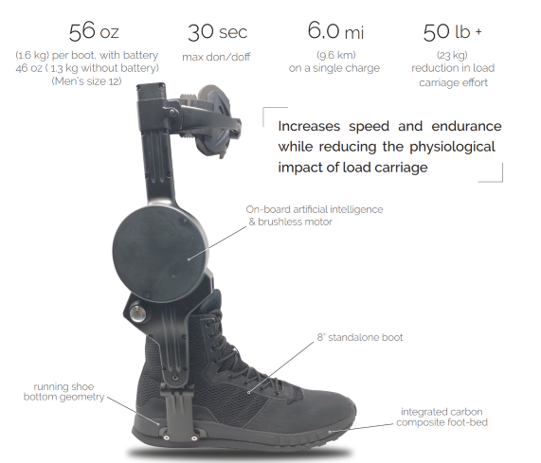

## 1.a. Load the data

We will simulate a phase based controller for an ankle exoskeleton. Positive moments and velocites at the ankle are in dorsiflexion. Note: I have also rotated the IMU on the right gastroc such that if the person is standing, positive x = right, positive y = forward (anterior), and positive z = upwards (superior), with the gyros following right hand rule.  Similarly to the previous homework, we will focus only on the right leg for simplicity.

clear; close all; clc
addpath('..\Sensor_data', 'MLPhaseController_functions\')
file2load  = "0deg_1.2ms_data.mat"; % Load the intermediate walking speed trial
load(file2load);
head(D) % Show the top 8 rows of the data table (D)

       Time            R_COP               L_COP                       R_F                             L_F                          R_Accel                          R_Gyro                            L_Accel                            L_Gyro                 R_Ankle_Angle    L_Ankle_Angle    R_Ankle_Velocity    L_Ankle_Velocity    R_Ankle_Moment    L_Ankle_Moment    R_Knee_Angle    L_Knee_Angle    R_Knee_Velocity    L_Knee_Velocity    R_Knee_Moment    L_Knee_Moment
    __________    ________________    ________________    _____________________________    ________

## 1.b Identify IMU signal that can be used for heel strike detection

In order to collect training data that doesn't require the treadmill, we will need to develop an IMU-based heel strike detector.  Using the original treadmill force-based heel strike detector (GetHeelStrikes) to plot the average and standard deviation segmented **sagittal plane** gyro vs gait phase (using SegmentDataByPhase).  "*errorbar*" allows to plot both the mean and std. dev.

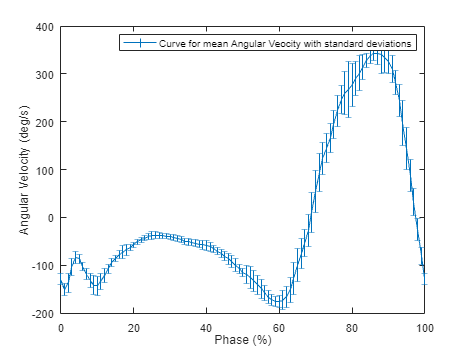

R_heel_strikes_from_Treadmill = GetHeelStrikesKey(D.R_F(:,3));
gait_phase = 0:1:100;
gyro_x = SegmentDataByPhaseKey(R_heel_strikes_from_Treadmill,D.R_Gyro(:,1));
gyro_x=gyro_x';
mean_gyroX= mean(gyro_x);
std_gyroX = std(gyro_x);

errorbar(gait_phase,mean_gyroX,std_gyroX)
xlabel("Phase (%)")
ylabel("Angular Velocity (deg/s)")
legend("Curve for mean Angular Veocity with standard deviations")

## 1.X IMU-based Heel Strike Detector

As seen above, the x axis of the gyro has a large peak around 90% of gait phase, or 10% before heel strike. **"****DetectHeelStrikesIMU.m**" takes in the sagittal plane gyro signal, and returns a vector containing the heel strikes.

- Low pass filter the data (Plotting the filtered data against the unfiltered data tremendously helps to make sure we are filtering it appropriately to get rid of inadvertent peaks due to noise!!).  

- Find when both of the following conditions are met: a) a data point is a peak (above both its neighbors), and b) is above some minimum threshold (200 deg/s).  

- Adds a short delay to better correspond with the heelstrikes detected by the force plates. 

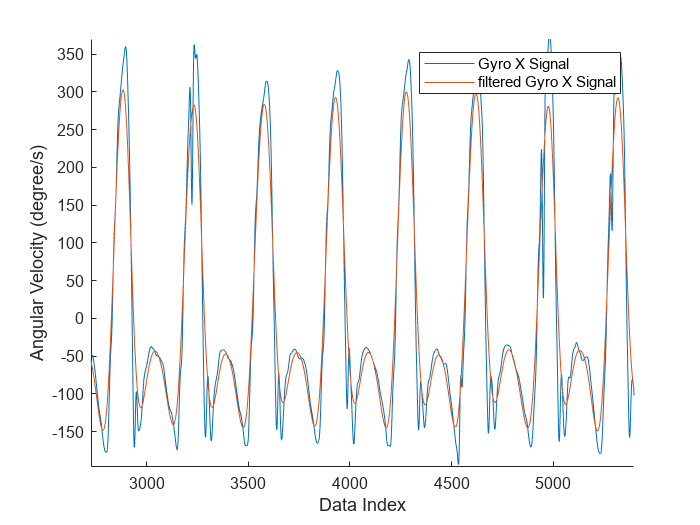

R_heel_strikes_from_IMU=DetectHeelStrikesIMU(D.R_Gyro(:,1));

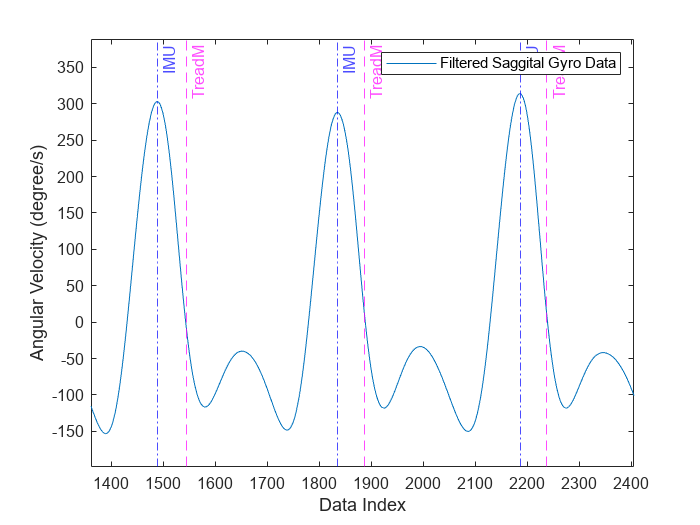

%plot
xline(R_heel_strikes_from_Treadmill,"--m",'TreadM')
xline(R_heel_strikes_from_IMU,"-.b",'IMU')
legend("Filtered Saggital Gyro Data")
xlim([1361 2405])
ylim([-199 389])
ylabel('Angular Velocity (degree/s)')
xlabel("Data Index")

## 2.a Gait Phase Label

**GetGaitPhase.m **takes in the time vector and the heel strike indices and returns the gait phase. Gait phase should be defined as 0 at heel strike and be approaching 100 at the next heel strike before being reset to 0. We can use "NaN" for all values before the first heel strike. Plot gait phase below by first iterating through the heel strikes to get a list (array) of the stride durations (difference in time between consecutive heel strikes).  Then, using a for loop to cycle through the whole time vector, keeping track of when the most recent heel strike was, and describing the time elapsed since the most recent heel strike as a fraction of the current stride duration.

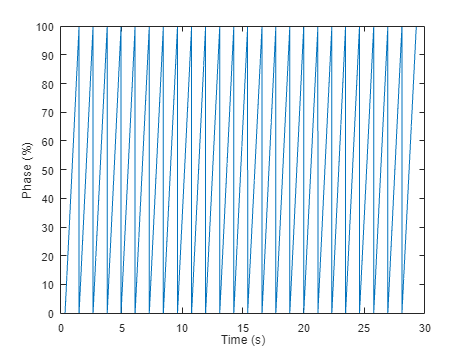

% Do not modify this code
D.R_Gait_Phase = GetGaitPhase(D.Time, R_heel_strikes_from_IMU);

figure;
plot(D.Time, D.R_Gait_Phase)
ylabel('Phase (%)')
xlabel('Time (s)')

## 3.a Gait phase regression using instantaneous values

The only way for us to label gait phase was in post-processing; we needed to know when the next heel strike would be.  We could not do this in real time, as our controller needs an instantaneous estimate of gait phase--meaning before the next heel strike has occurred!  The idea here is to use sensors (like the IMU) to *predict* gait phase, using only the current and past data, but no future data. That way, our gait phase estimator can be capable of being deployed in real time.

To start, we will use the instantaneous values of the following signals: (["R_Accel", "R_Gyro", "R_Ankle_Angle", "R_Ankle_Velocity"]) to predict R_Gait_Phase with a linear model.  Inspect the output of the "mdl," which is a LinearModel object containing the coefficients for each of our eight channels, the intercept, some statistics for each parameter, and some performance metrics such as R^2 and RMSE.  Nothing specific to do here, just read through the following code.

%Grab our signals, convert to matrix:
Sensors = table2array(D(:, ["R_Accel", "R_Gyro", "R_Ankle_Angle", "R_Ankle_Velocity"])); 
mdl = fitlm(Sensors, D.R_Gait_Phase )

mdl = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6 + x7 + x8

Estimated Coefficients:
                   Estimate        SE         tStat       pValue   
                   _________    _________    _______    ___________

    (Intercept)       96.466      0.79696     121.04              0
    x1              -0.96654      0.11228     -8.608     8.7358e-18
    x2                1.6139     0.070607     22.858    2.3952e-112
    x3               -4.3064     0.077795    -55.356              0
    x4             -0.054879    0.0017233    -31.845    1.4085e-210
    x5              -0.74646      0.01415    -52.753              0
    x6              -0.14843    0.0046008    -32.262    9.1183e-216
    x7         

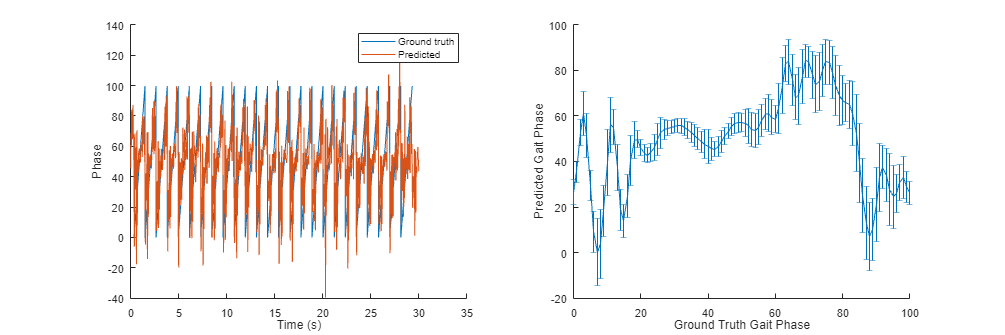

predicted_phase = mdl.predict(Sensors);
fig3a = figure; hold on
subplot(1,2,1); hold on
plot(D.Time, D.R_Gait_Phase)
plot(D.Time, predicted_phase)
xlabel('Time (s)')
ylabel('Phase')
legend(["Ground truth", "Predicted"])

predicted_phases = SegmentDataByPhaseKey(R_heel_strikes_from_Treadmill, predicted_phase);
subplot(1,2,2); hold on
errorbar(0:1:100, mean(predicted_phases'), std(predicted_phases'))
fig3a.Position(3:4)=[1200,400];
xlabel("Ground Truth Gait Phase")
ylabel("Predicted Gait Phase")

## 3.b Feature Extraction

Looking at the RMSE, as well as the overall shape of the plot, our gait phase model using instantaneous values didn't do too well.  Adding some new features of these signals (so called "**feature engineering"**) which will give the model some information about the sensor behaviors during a brief window of time preceding the instantaneous values.  

**"GetFeatures"** takes in the window size to use, data table D, and the names of the channels to use, and returns a big matrix containing the 1) mean, 2) min, 3) max, and 4) instantaneous value of each feature. It's okay if it returns NaN for the first values, when there has not been enough data to apply our window. Returned matrix should be 9001 x 32 (4 features x 8 channels).

% Do not modify this code
channels_to_use = ["R_Accel", "R_Gyro", "R_Ankle_Angle", "R_Ankle_Velocity"];
window_size = 100;
Features = GetFeatures(window_size, D, channels_to_use);

## 3.c Fit linear model with features

Using this new feature matrix, fitting a linear model to predict R_Gait_Phase. Note the improvement to the RMSE compared to that found in 3.a. 

mdl_update = fitlm(Features, D.R_Gait_Phase)

mdl_update = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6 + x7 + x8 + x9 + x10 + x11 + x12 + x13 + x14 + x15 + x16 + x17 + x18 + x19 + x20 + x21 + x22 + x23 + x24 + x25 + x26 + x27 + x28 + x29 + x30 + x31 + x32

Estimated Coefficients:
                    Estimate        SE         tStat        pValue   
                   __________    _________    ________    ___________

    (Intercept)       -1.3874       3.4144    -0.40635         0.6845
    x1                 8.3743      0.59524      14.069     1.8238e-44
    x2                0.99493      0.30575      3.2541      0.0011419
    x3                -1.4437        0.324      -4.456     8.4552e-06
    x4               -0.73529      0.13626      -5.396     6.9939e-08
    x5         

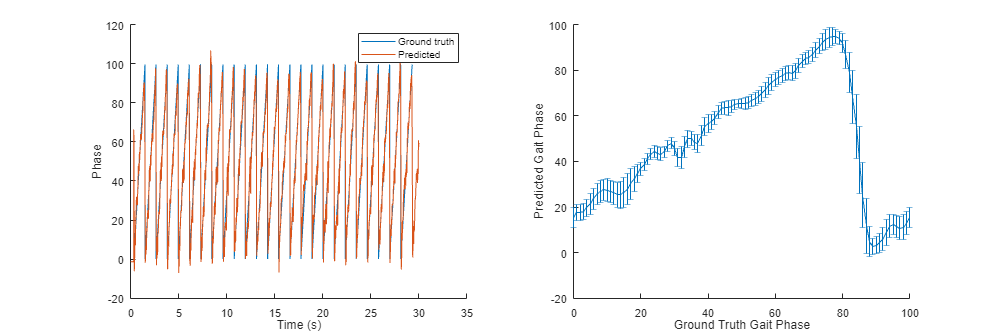

predicted_phase_32Features = mdl_update.predict(Features);
fig3c = figure; hold on
subplot(1,2,1); hold on
plot(D.Time, D.R_Gait_Phase)
plot(D.Time, predicted_phase_32Features)
xlabel('Time (s)')
ylabel('Phase')
legend(["Ground truth", "Predicted"])

predicted_phases_32segmented = SegmentDataByPhaseKey(R_heel_strikes_from_Treadmill, predicted_phase_32Features);
subplot(1,2,2); hold on
errorbar(0:1:100, mean(predicted_phases_32segmented'), std(predicted_phases_32segmented'))
fig3c.Position(3:4)=[1200,400];
xlabel("Ground Truth Gait Phase")
ylabel("Predicted Gait Phase")

**ANS:   The RMSE is 8.74 with R-squared Value of 0.909.**

## 3.d Mapping Phase to Exo Torque

Looking a little better, but still not great!  Let's go with it for now though.  How can we use gait phase to control the exoskeleton?  

Our goal is for the exoskeleton to approximately produce 25% of the bological ankle moment. Define a spline using Matlab's PCHIP function (https://www.mathworks.com/help/matlab/ref/pchip.html).  Use no more than six "spline points" to define this spline, with the x points ranging from 0 to 100. 

On the same plot, **plot the two following curves**:

- the average (with errorbars showing std) biological ankle moment (again, use "SegmentDataByPhase"), **multiplied by 0.25**

- Your PCHIP spline, assuming gait phase is perfect.

On another plot, **plot the two following curves****:**

- the average (with errorbars showing std) biological ankle moment (again, use "SegmentDataByPhase"), multiplied by 0.25

- the average (with errorbars showing std) exoskeleton torque, using your PCHIP spline.

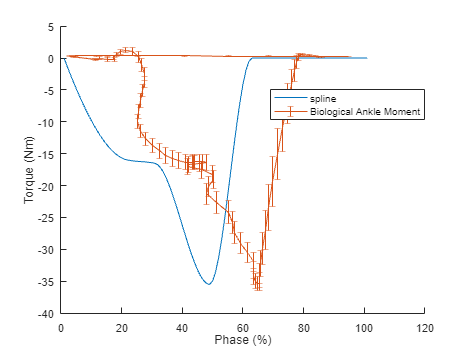

%Spline 
y=[0,-16,-16.5,-35.5,0,0];%,-14.5,-16.5 Function perfect with 7 points!!
x=[0,21,30,48,62,100];%17,32 Function perfect with 7 points!!
xq2=0:1:100;
sp=pchip(x,y,xq2);

%Ankle Torque
Ankle_Moment = 0.25*SegmentDataByPhaseKey(R_heel_strikes_from_Treadmill,D.R_Ankle_Moment);
Ankle_Moment=Ankle_Moment';
mean_T_ankle= mean(Ankle_Moment);
std_T_ankle = std(Ankle_Moment);

%Figure Plotting 1 
figure;
hold on;
plot(sp)
errorbar(mean(predicted_phases_32segmented',1),mean_T_ankle,std_T_ankle)
xlabel('Phase (%)')
ylabel('Torque (Nm)')
legend('spline','Biological Ankle Moment')
hold off;

legend("Position", [0.57694,0.66181,0.32679,0.082143])

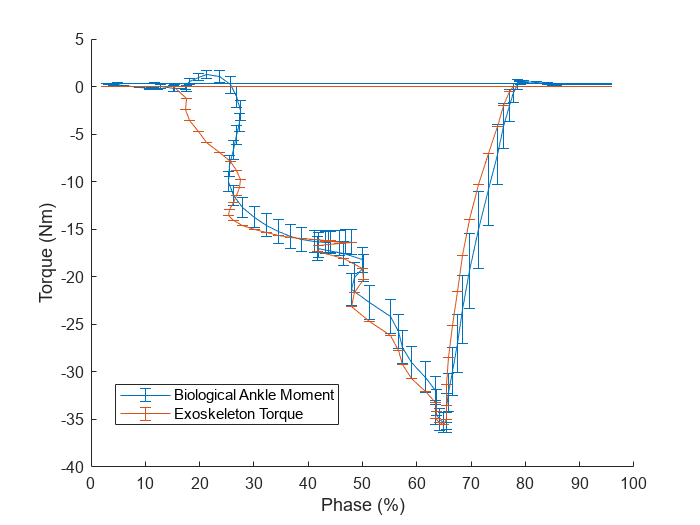

figure;
hold on;
errorbar(mean(predicted_phases_32segmented',1),mean_T_ankle',std_T_ankle');
mean_sp = mean(sp',2);
std_sp = std(sp',0,2);
errorbar(mean(predicted_phases_32segmented',1),mean_sp', std_sp')
xlabel('Phase (%)')
ylabel('Torque (Nm)')
legend('Biological Ankle Moment','Exoskeleton Torque')
legend("Position", [0.16404,0.1899,0.31964,0.079286])

**Question**:

There seem to be large plantarflexion torque occuring around heel strike (95% - 100%, and 0% - 5%).  What is causing this?

1) Plantarflexion happens around 95-100% of gait cycle, which is consecutively followed by its 0-5%, because the muscles are actually doing negative work by using eccentric force to lower down the leg in swing.

2) During then late swing phase, the action of gravity force is also acting downwards but, as the muscle pulling up is absent, plantarflexion occuers naturally

3) However, this characterstic is a by-product and not a desired outcome of late swing phase and hence, should not be imitated by the phase controller.

4) Additionally,for a controller, the holding torque **should be maintained towards the dorsiflexion side to initiate a proper heel strike****, without any toe-ins and tip offs.**

## 4.a Phase: Solving the Discontinuity

One of the tricky issues with our naive approach to phase-based control is that we have a *discontinuity* at heel strike, where right before heel strike gait phase is approaching 100, but right at heel strike we jump down to 0.  Our regression is trying to learn that discontuity, but it can't do it perfectly, so it naturally passes through several intermediate values between 1 and 0.  Unfortunately, we map many of those intermediate values to a torque.  

To fix this issue, we can take advantage of a different way to describe phase--as a rotation.  Similarly, *theta* has a discontinuity between 0 and 2*pi, but we can represent theta (a single vector) in a different way without a discontinuity by taking the sin and cos of theta (two vectors), while assuming a radius of 1.  

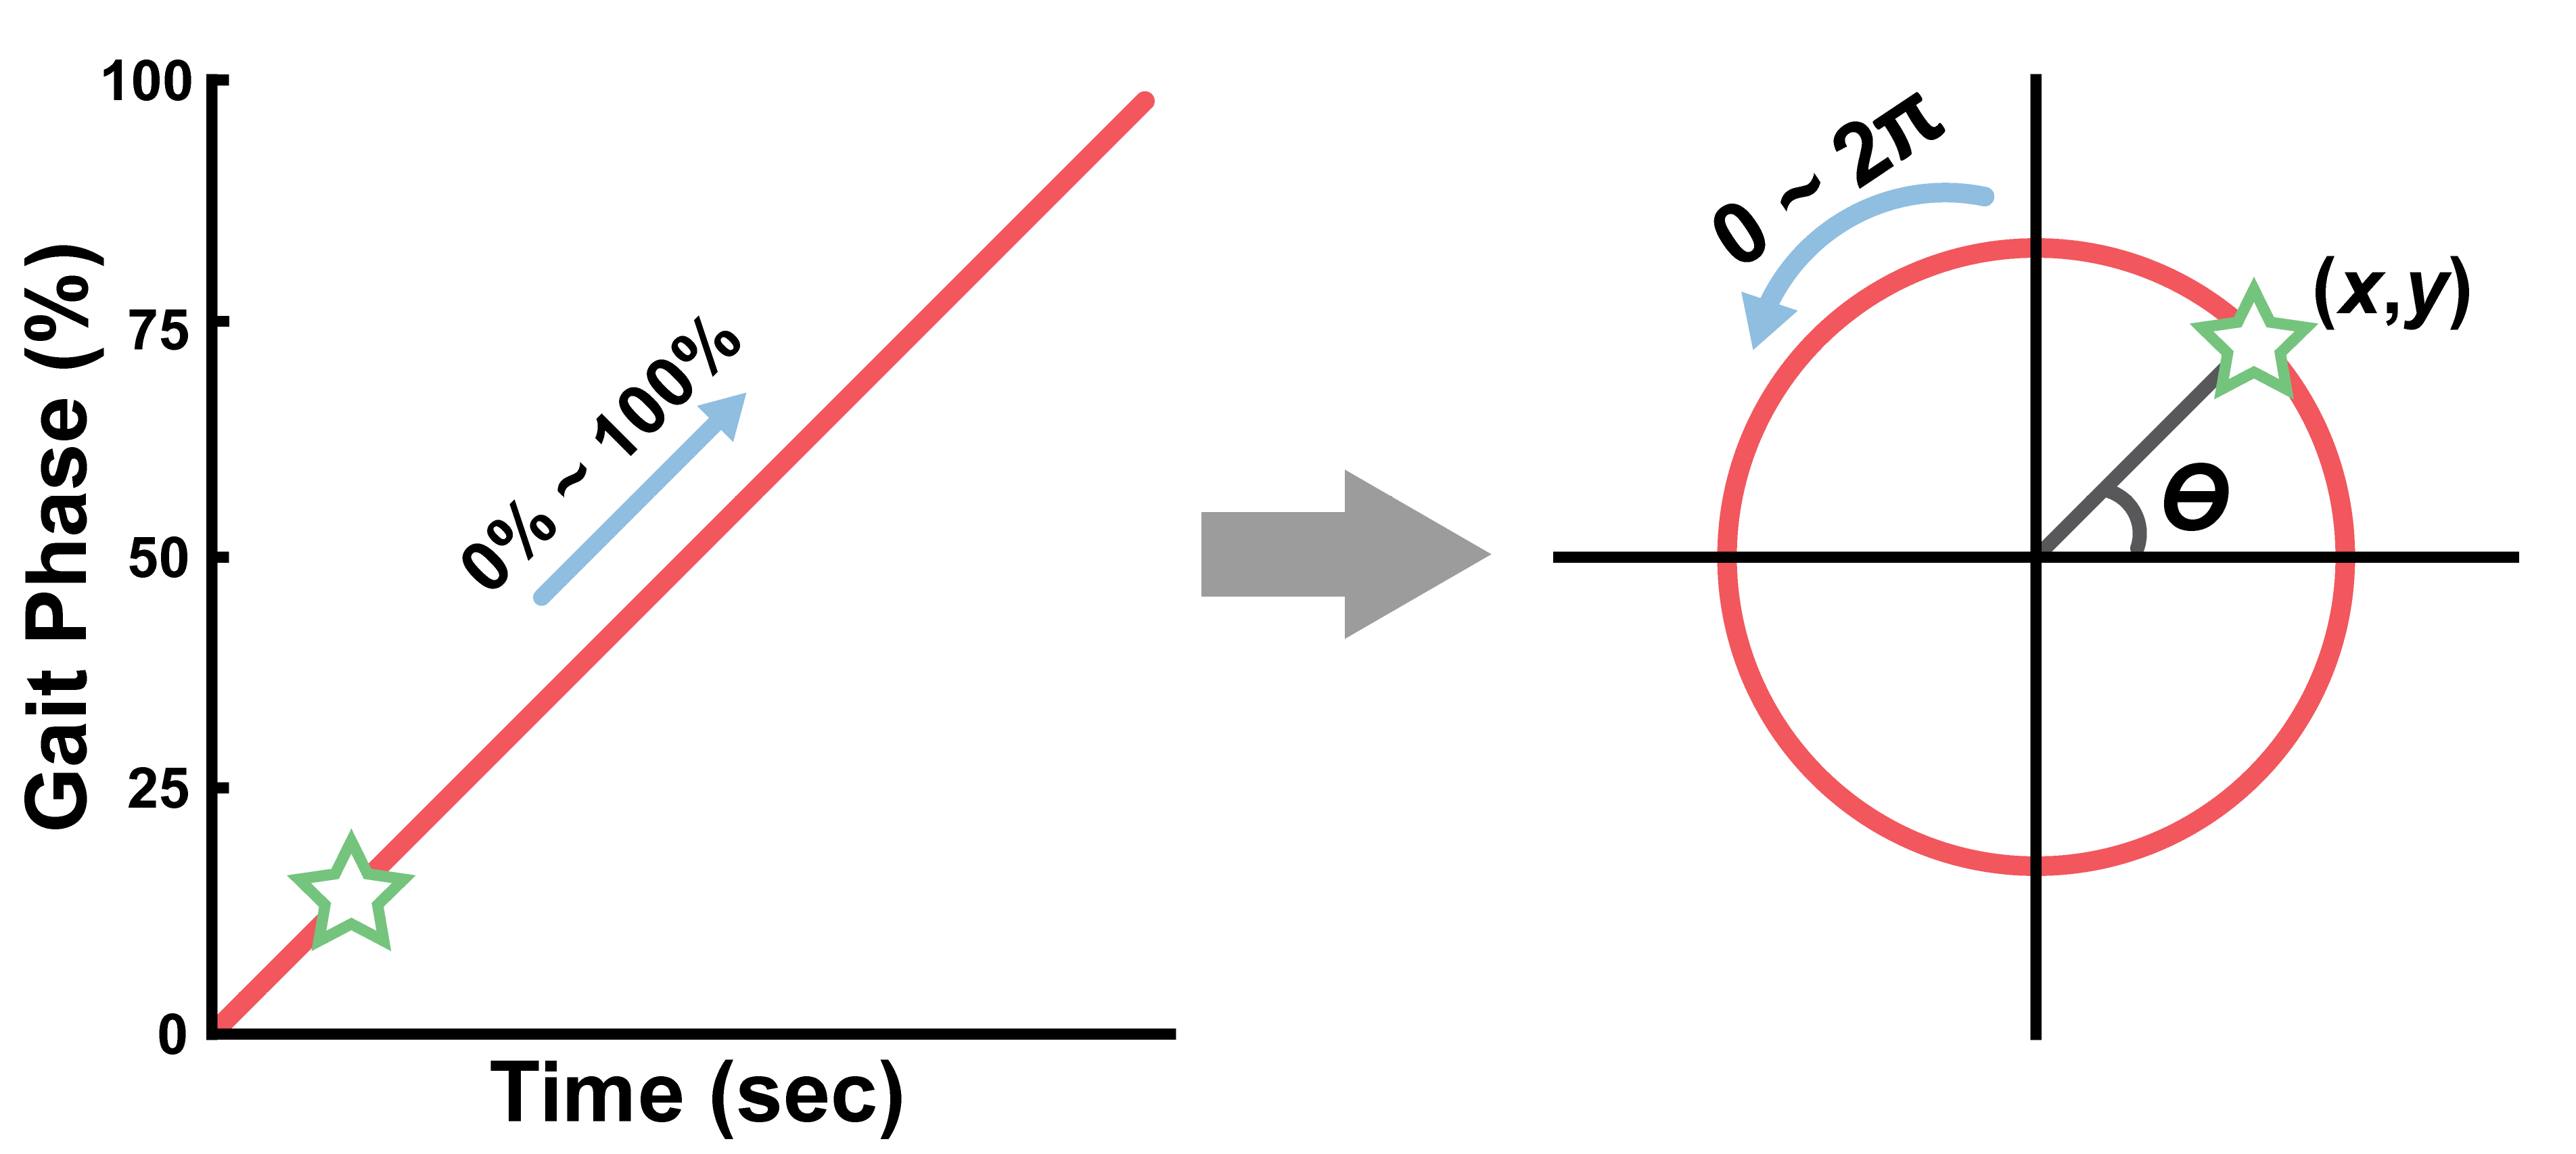

For more information on this approach, see: https://ieeexplore.ieee.org/ielaam/8253409/9007555/8941004-aam.pdf

**Approach:** Use D.R_Gait_Phase as a rotation between (0 and 2*pi) rather than a number between 0 and 100.  Split this "rotation" into two vectors--the cos and sin components.  Train two independent linear regressions to predict these components using the same feature matrix as the previous step.  Finally, combine the prediction of these regressions using atan2. 

**Show the following plots:**

- Predicted gait phase vs time and actual gait phase vs time (zoom in a little to show how well it did).

- A phase plot of predicted_phase_x vs predicted_phase_y (see below for the goal)

*Note: There's a little diligence required in converting things to and from angles.  Unfortunately for our purposes, atan2 returns angles in the interval [-pi, pi] rather than [0 2pi].  The easiest option is probably to subtract pi from your angle, so that you are now mapping [0 100] to [-pi, pi].  Then train linear models, and when using atan2, we will just need to do the inverse map from [-pi pi] to [0 100].*

D.R_Gait_Phase(1:101) = 0;
D.R_Gait_Phase(8847:end) = 0;
gait_rad=(D.R_Gait_Phase*(2*pi)/100)-pi;
sin_=sin(gait_rad);
cos_=cos(gait_rad);
mdl_sin=fitlm(Features,sin_)

mdl_sin = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6 + x7 + x8 + x9 + x10 + x11 + x12 + x13 + x14 + x15 + x16 + x17 + x18 + x19 + x20 + x21 + x22 + x23 + x24 + x25 + x26 + x27 + x28 + x29 + x30 + x31 + x32

Estimated Coefficients:
                    Estimate          SE         tStat        pValue   
                   ___________    __________    ________    ___________

    (Intercept)      -0.021355      0.011128      -1.919        0.05501
    x1                 -0.1139     0.0077828     -14.634     6.0767e-48
    x2                0.033466     0.0039125      8.5535     1.3919e-17
    x3               -0.050174      0.003132      -16.02     5.7755e-57
    x4              -0.0050806     0.0017542     -2.8963      0.0037855
    x5       

mdl_cos=fitlm(Features,cos_)

mdl_cos = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6 + x7 + x8 + x9 + x10 + x11 + x12 + x13 + x14 + x15 + x16 + x17 + x18 + x19 + x20 + x21 + x22 + x23 + x24 + x25 + x26 + x27 + x28 + x29 + x30 + x31 + x32

Estimated Coefficients:
                    Estimate          SE         tStat       pValue  
                   ___________    __________    _______    __________

    (Intercept)        -0.8834      0.021536     -41.02             0
    x1                 0.12994      0.015062     8.6268    7.3952e-18
    x2               -0.024256     0.0075719    -3.2035     0.0013626
    x3                0.086471     0.0060614     14.266     1.133e-45
    x4               -0.028676     0.0033949    -8.4468    3.4659e-17
    x5            

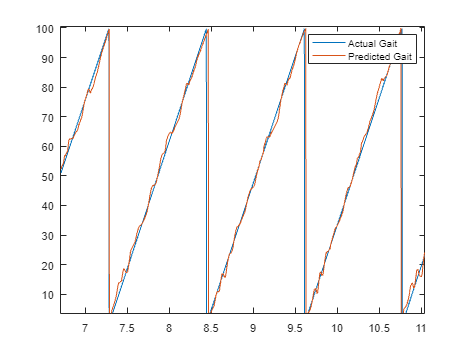

predicted_sin=mdl_sin.predict(Features);
predicted_cos=mdl_cos.predict(Features);

D.R_gait_cyclic=(atan2(sin_,cos_)+pi)*100/(2*pi);
exo_pred_cyc=(atan2(predicted_sin,predicted_cos)+pi)*100/(2*pi);
figure;
plot(D.Time,D.R_gait_cyclic);
hold on;
plot(D.Time,exo_pred_cyc);
legend('Actual Gait','Predicted Gait')

hold off
xlim([6.71 11.04])
ylim([3.6 100.6])

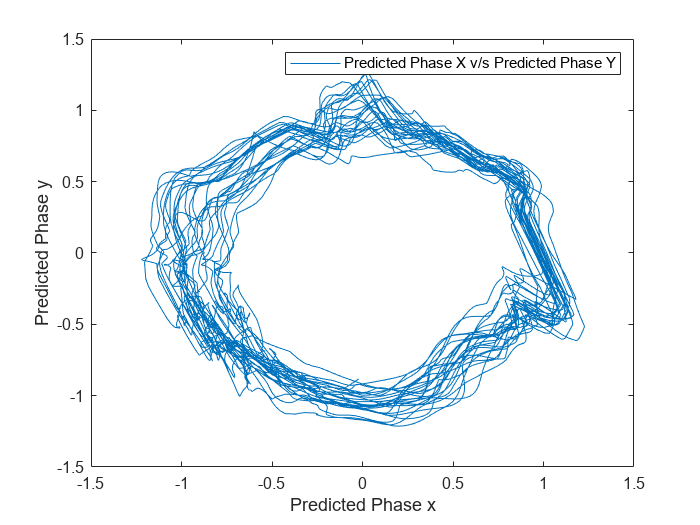

figure;
plot(predicted_sin,predicted_cos)%% Vertical Line exists because of NaN values
xlabel('Predicted Phase x')
ylabel('Predicted Phase y')
legend('Predicted Phase X v/s Predicted Phase Y')

## 4.b Torque vs Phase Revisited

Now that the phase prediction is much better, let's see how our exo torque looks.  Using the same type of PCHIP spline, plot the exo torque as a function of predicted gait phase, along with the target, which is 25% of the biological torque.  

Calculate the RMSE between our exo's torque and our target.*Trying to get RMSE below 2.2 Nm.*

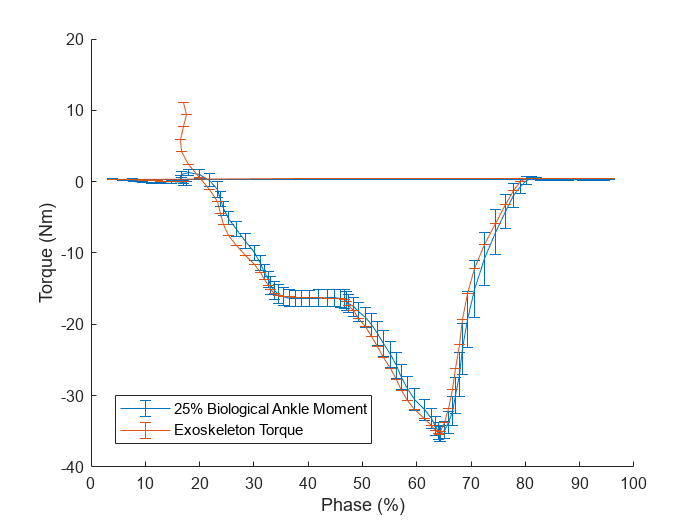

%Spline 
x = [7,20.5,30,48,63,100];
y = [-1.09,-16,-16.5,-35.5,0.5,0];
xq2=0:1:100;
sp=pchip(x,y,xq2);

%Ankle Torque
Ankle_Moment = 0.25*SegmentDataByPhaseKey(R_heel_strikes_from_Treadmill,D.R_Ankle_Moment);
Ankle_Moment=Ankle_Moment';
mean_T_ankle= mean(Ankle_Moment);
std_T_ankle = std(Ankle_Moment);

seg_exo_pred_cyc=SegmentDataByPhaseKey(R_heel_strikes_from_Treadmill,exo_pred_cyc);
mean_exo = mean(seg_exo_pred_cyc');


%Figure Plotting 2
figure;
hold on;
errorbar(mean_exo,mean_T_ankle,std_T_ankle);
mean_s_exo = mean(sp',2);
std_s_exo = std(sp',0,2);

errorbar(mean_exo,mean_s_exo',std_s_exo');
xlabel('Phase (%)')
ylabel('Torque (Nm)')
legend('25% Biological Ankle Moment','Exoskeleton Torque')
legend("Position", [0.16451,0.15436,0.36679,0.092619])
hold off;

rmse(mean_T_ankle,mean_s_exo','all')

ans = 2.1777

## 4.c Try our controller on slow walking

Load "0deg_0.9ms_HW4.mat" and try our new controller (which was only trained on the intermediate walking speed) on slow walking. 

**Plots**:

-  Predicted gait phase vs time, and actual gait phase vs time. Zoom in a bit for clarity.  What's the RMSE?

-  25% of Biological torque vs time, and our exo torque vs time. 

Our simple linear model does pretty well! [10]

file2load  = "0deg_0.9ms_HW4.mat"; % Load the intermediate walking speed trial
temp_ = load(file2load);
D_slow = temp_.D;
head(D_slow)

       Time            R_COP               L_COP                       R_F                              L_F                          R_Accel                           R_Gyro                             L_Accel                           L_Gyro                R_Ankle_Angle    L_Ankle_Angle    R_Ankle_Velocity    L_Ankle_Velocity    R_Ankle_Moment    L_Ankle_Moment    R_Knee_Angle    L_Knee_Angle    R_Knee_Velocity    L_Knee_Velocity    R_Knee_Moment    L_Knee_Moment
    __________    ________________    ________________    _____________________________    _______

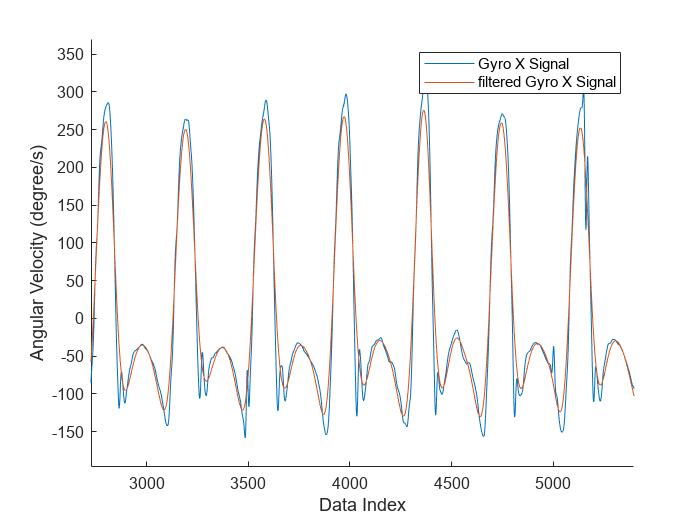

R_slow_heel_strikes_from_IMU=DetectHeelStrikesIMU(D_slow.R_Gyro(:,1));

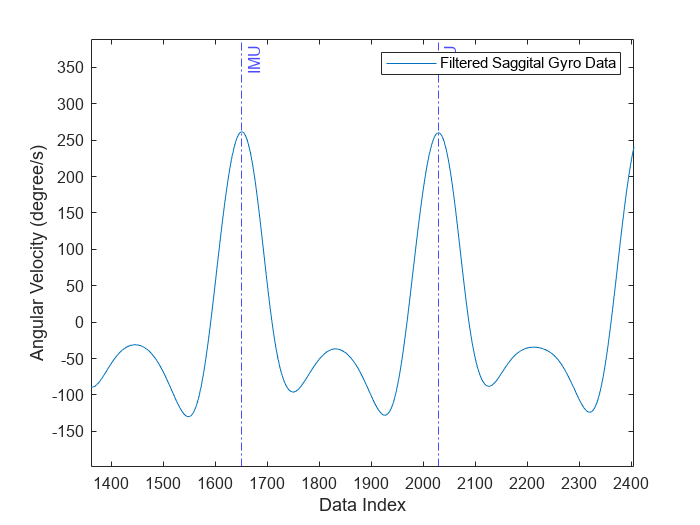

%plot
xline(R_slow_heel_strikes_from_IMU,"-.b",'IMU')
legend("Filtered Saggital Gyro Data")
xlim([1361 2405])
ylim([-199 389])
ylabel('Angular Velocity (degree/s)')
xlabel("Data Index")

D_slow.R_Gait_Phase = GetGaitPhase(D_slow.Time, R_slow_heel_strikes_from_IMU);

% Getting Features
channels_to_use = ["R_Accel", "R_Gyro", "R_Ankle_Angle", "R_Ankle_Velocity"];
window_size = 100;
Features_slow = GetFeatures(window_size, D_slow, channels_to_use);

%Converting to sin , cos
gait_slow_rad=(D_slow.R_Gait_Phase*(2*pi)/100)-pi;
slow_sin_=sin(gait_slow_rad);
slow_cos_=cos(gait_slow_rad);


%Model Fitting
mdl_slow_sin=fitlm(Features_slow,slow_sin_)

mdl_slow_sin = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6 + x7 + x8 + x9 + x10 + x11 + x12 + x13 + x14 + x15 + x16 + x17 + x18 + x19 + x20 + x21 + x22 + x23 + x24 + x25 + x26 + x27 + x28 + x29 + x30 + x31 + x32

Estimated Coefficients:
                    Estimate          SE          tStat        pValue   
                   ___________    __________    _________    ___________

    (Intercept)        -0.2648      0.049699      -5.3281     1.0181e-07
    x1                 -0.1034     0.0063631      -16.251     1.6718e-58
    x2             -0.00095272     0.0036128     -0.26371        0.79201
    x3               -0.054423     0.0049483      -10.998     5.9985e-28
    x4              -0.0029968     0.0015546      -1.9277        0.05393
    

mdl_slow_cos=fitlm(Features_slow,slow_cos_)

mdl_slow_cos = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6 + x7 + x8 + x9 + x10 + x11 + x12 + x13 + x14 + x15 + x16 + x17 + x18 + x19 + x20 + x21 + x22 + x23 + x24 + x25 + x26 + x27 + x28 + x29 + x30 + x31 + x32

Estimated Coefficients:
                    Estimate          SE         tStat        pValue   
                   ___________    __________    ________    ___________

    (Intercept)        0.95176      0.050423      18.875     7.0161e-78
    x1               -0.092867     0.0064558     -14.385     2.2505e-46
    x2                0.041587     0.0036655      11.346     1.2741e-29
    x3                0.022636     0.0050204      4.5088     6.6066e-06
    x4               0.0017567     0.0015773      1.1137        0.26543
    x5  

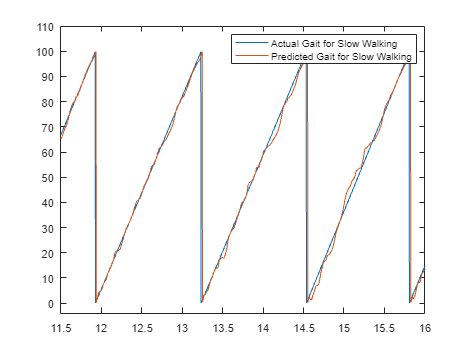

%Predictions
slow_predicted_sin=mdl_slow_sin.predict(Features_slow);
slow_predicted_cos=mdl_slow_cos.predict(Features_slow);

D_slow.R_gait_cyclic=(atan2(slow_sin_,slow_cos_)+pi)*100/(2*pi);
exo_slow_pred_cyc=(atan2(slow_predicted_sin,slow_predicted_cos)+pi)*100/(2*pi);
figure;
plot(D_slow.Time,D_slow.R_gait_cyclic);
hold on;
plot(D_slow.Time,exo_slow_pred_cyc);
legend('Actual Gait for Slow Walking','Predicted Gait for Slow Walking')

xlim([11.5 16])
ylim([-4 110])

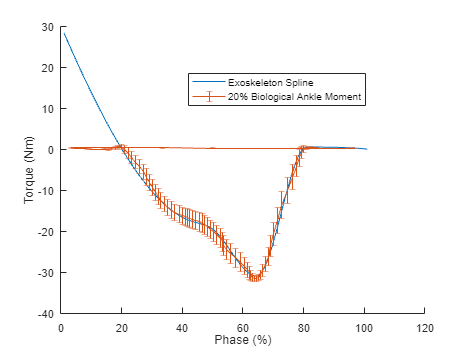

%Spline 
x_slow = [20,40,48,63.5,80,100];
y_slow = [-1.09,-17,-19,-31,0.5,0];
xq2=0:1:100;
sp_slow=pchip(x_slow,y_slow,xq2);

%Ankle Torque
Ankle_Moment_slow = 0.25*SegmentDataByPhaseKey(R_slow_heel_strikes_from_IMU,D_slow.R_Ankle_Moment);
Ankle_Moment_slow=Ankle_Moment_slow';
slow_mean_T_ankle= mean(Ankle_Moment_slow);
slow_std_T_ankle = std(Ankle_Moment_slow);

seg_slow_exo_pred_cyc=SegmentDataByPhaseKey(R_slow_heel_strikes_from_IMU,exo_slow_pred_cyc);

mean_slow_s_exo = mean(sp_slow',2);
std_slow_s_exo = std(sp_slow',0,2);
slow_mean_exo = mean(seg_slow_exo_pred_cyc');

%Figure Plotting 1
figure;
hold on;
plot(sp_slow);
errorbar(slow_mean_exo,slow_mean_T_ankle,slow_std_T_ankle);

xlabel('Phase (%)')
ylabel('Torque (Nm)')
legend('Exoskeleton Spline','20% Biological Ankle Moment')
legend("Position", [0.40347,0.7002,0.375,0.092619])
hold off;

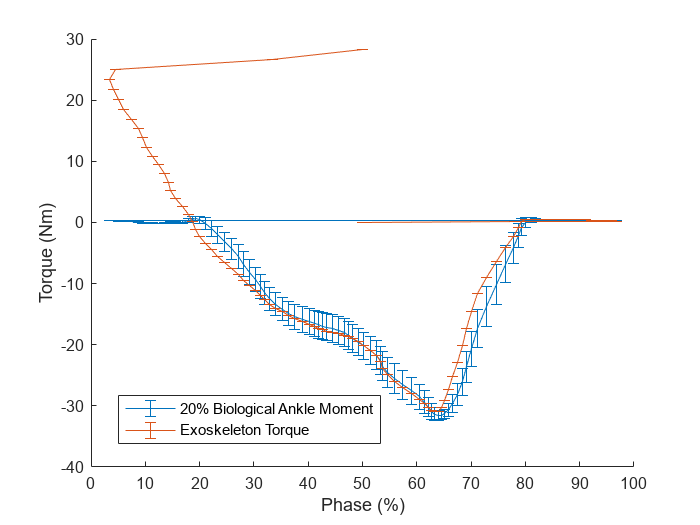

%Figure Plotting 2
figure;
hold on;
errorbar(slow_mean_exo,slow_mean_T_ankle,slow_std_T_ankle);
mean_slow_s_exo = mean(sp_slow',2);
std_slow_s_exo = std(sp_slow',0,2);

errorbar(slow_mean_exo,mean_slow_s_exo',std_slow_s_exo');
xlabel('Phase (%)')
ylabel('Torque (Nm)')
legend('20% Biological Ankle Moment','Exoskeleton Torque')
legend("Position", [0.16893,0.15436,0.375,0.092619])
hold off;

%RMSE for slow Walking
rmse(slow_mean_T_ankle,mean_slow_s_exo','all')

ans = 7.3111

## 5.a Alternative Control: EMG 

We have also recorded EMG from the medial gastroc, which is one of the major plantaflexors.  This is sampled at a higher frequency, because there is important information contained above the nyquist freqeuncy for the markers and IMUs (300/2 = 150 Hz).

First, plot the raw_EMG (mV) on the same plot as ankle moment (Nm), to inspect if there is a general trend.  We will need to use the sampling frequency to create a new time vector for the EMG.  Zoom into the plot to show a couple strides.

load('0deg_1.2ms_tracked.mat')
fs_EMG = round(qtm_0deg_1_2ms_tracked.Analog(2).Frequency);
R_EMG_gastroc = qtm_0deg_1_2ms_tracked.Analog(2).Data(1,:)';
disp("fs_EMG: " + fs_EMG)

fs_EMG: 4000


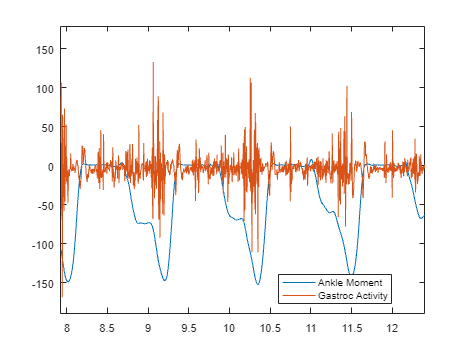

time_original_data=linspace(0,1/fs_EMG*(length(R_EMG_gastroc)-1), length(R_EMG_gastroc));
time_resampled=resample(time_original_data,9001,120013)';
R_EMG_gastroc_t=resample(R_EMG_gastroc,9001,120013);

figure;
plot(D.Time,D.R_Ankle_Moment);
hold on;
plot(time_resampled,R_EMG_gastroc_t);
legend('Ankle Moment','Gastroc Activity')
legend("Position", [0.5956,0.1404,0.23964,0.079286])

xlim([7.93 12.40])
ylim([-189 179])

## 5.b Proportional Myoelectric Control

It seems like maybe there's a trend there, but we need to process the EMG to have a useable signal. Perform our sequence of EMG processing steps to get a general envelope: highpass filter with a 200 Hz filter to remove drift, rectify (take the absolute value), and then lowpass filter.  Pick a cutoff frequency for the lowpass filter that seems to do a good job of creating a profile that gives the EMG profile a similar profile to ankle torque.  Finally, downsample to 300 Hz, which we use for the rest of our data (I've included a helpful function "ResampleByFreq" to aid with this), and add a gain, such that this processed EMG signal closely matches with 25% of the biological ankle moment.  **Plot** EMG-based torque vs Time and 25% of ankle moment vs Time (and zoom in to a couple strides).** Calculate RMSE**.

How low can you get the RMSE by modifying your filtering and gain value? 

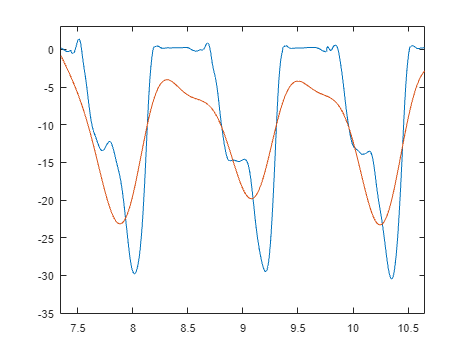

% Your code here
%HIGH PASS FILTER
%fc_EMG=0.707*400; %Cutoff frequency is 70.7 of the max signal frequency  %(mean(qtm_0deg_1_2ms_tracked.Analog(2).Frequency));
ankle_moment_25=0.2*D.R_Ankle_Moment;
fc_EMG_high=45; %Given in question
[b_high,a_high] = butter(4,fc_EMG_high/(fs_EMG/2),'high'); %4th order, zero-lag high-pass
filtered_EMG_gastroc=filtfilt(b_high,a_high,R_EMG_gastroc);
Abs_filtered_gastroc=abs(filtered_EMG_gastroc);%Absolute Value

%LOW PASS FILTER
fc_EMG_low=1.59;
[b_low,a_low] = butter(4,fc_EMG_low/(fs_EMG/2),'low'); %4th order, zero-lag low-pass
filtered_EMG_gastroc=filtfilt(b_low,a_low,Abs_filtered_gastroc);

%Resampling
fs_downscale=300;
Resample_filt_EMG_gastroc=-1*ResampleByFreq(filtered_EMG_gastroc,fs_EMG,fs_downscale);

%Plotting
figure;
plot(D.Time,ankle_moment_25);
hold on;
plot(D.Time,Resample_filt_EMG_gastroc);

xlim([7.35 10.65])
ylim([-35 3.1])

rmse(ankle_moment_25,Resample_filt_EMG_gastroc,'all')

ans = 5.7970

**Questions and Answers**:

**1)) EMG control doesn't seem to be as easy to map to biological torque, at least with this analysis.  What are other factors or variables could we use to potentially improve our mapping between EMG and torque, and why? [5*]**

1) Biological joint angle is reflective of the muscle actiivity in a particular direction and can be used to map the torque in conjuction to EMG.

2) Power is the product of force and velocity, and is reflected by the muscle activity i.e. Power required increases if the muscles activity increases. This power can also be calculated using breathing rate, which can help to time the EMG signals to remove noise.

3) We could use a combination of EMG graphs of agonist and its antagonistic muscle superimposed together to mark the peaks and valleys in each, which could be the most accurate predictor of peak joint torque at given time. This approach could help detect and eliminate noise, drift, lag ,etc.

**2)) Compare and contrast the pros and cons of phase-based control and EMG control.  Which would you be more optimistic could be acceptable to users? Which would require more work to make it ready for users to take home? [5*]**

**Pros of phase-based controller:**

1) The phase based controller would be easier to use and can be tuned to the individual's walking pattern at once, and would not require maintenance. 

2) Futhermore,using Machine learning to predict phases and stance could further help improve the accuracy of torques delivered for given walking conditions.

3) Phase-based control is highly user-independent hence, is a promising approach for the leg exoskeletons.

**Pros of EMG controller:**

1) EMG control can utilize a person's input to dring the displacement by generating proportional amount of torque and could work better than other contol approaches for unforeseen conditions where the person has to stop abruptly or change gait. 

2) Futhermore, the control approach is not generalized accross population on which the data is collected, and can be integrated much easier into the gait patterns.

**Cons of Phase based Controller:**

1) Phase based control is depedent on accuracy of data collected, if there is biased or corrupted data, the prediction of phase could fail. 

2) Phase-based control is dependent on the combination of the variables selected and some combinations would not perform robustly, for a huge variety of gait cases. 

3) The phase controller could fail in instances of sudden halting or instantaneous changes in gait, unless correct combination of variables is chosen.

**Cons of EMG Controller:**

1) EMG controller is dependent on the inital positioning of sensors and even slight change in the sensor position during walking could induce large errors in prediction of gait.

2) It is difficult to detect and subsequently overcome noise, drifts, and other signal conditioning problems, solely bassed on the EMG signal itself.

3) Mapping of EMG to Torque, as seen above, is difficult unless some other variable is used in conjunction to validate the EMG signal.

4) Amputated muscles are seen to not behave as a natural intact muscle would, and hence would not generate EMG at times.

**As the above stated-Cons of EMG controller are more pronouced, especially that the controller would fail if the EMG sensor placement is improper or changes during walking, it is less probable to be used autonomously by users.**